% roverLocation = [42.293346 -71.264365]
% targetWaypoint = [42.293389 -71.264359]
roverLocation = [0 0]

roverLocation =      0     0


targetWaypoint = [2 2]

targetWaypoint =      2     2


roverBearing = 0

roverBearing = 0

    % Initialize the waypoint vector
    waypointSteeringVector = zeros(71,1);
    
    % Do math to find radius of bumblebee circle
    xdist = abs(targetWaypoint(1) - roverLocation(1))

xdist = 2

    ydist = abs(targetWaypoint(2) - roverLocation(2))

ydist = 2

    omega = 360 - roverBearing

omega = 360

    a = 1-cosd(omega)^2-sind(omega)^2

a = 0

    b = 2*(cosd(omega)*xdist + sind(omega)*ydist)

b = 4

    c = -(xdist^2 + ydist^2)

c = -8

    radius = roots([b c])

radius = 2

    %converting radius to meters
%     radius_meters = radius*111000
    % converting to bearing
%     bearing = (radius - eqn(2))./(eqn(1))
    a = .152;
    l = 0.308

l = 0.3080

    bearing = acotd((radius^2 - a^2)/(l^2));
     
     
    % finding the index for the turn angles to change
    bearing = (round(bearing))

bearing = 1

    turnAngles = -35:10:35 % 8 vectors( y range is from -1 to 1)

turnAngles =    -35   -25   -15    -5     5    15    25    35


    ind = find(abs(turnAngles - bearing) <= 0.001);
    
    % Change the steering vector
    waypointSteeringVector(ind) = 0.5;

    f(x) = a*exp(b*x) + c*exp(d*x)

       where x is normalized by mean 21.25 and std 11.09

Coefficients:

       a =    0.002742

       b =      -5.253

       c =       1.425

       d =     -0.4118

    angles = [10 15 25 35];
radius = [2.73 1.85 1.24 0.855]; % in meters
eqn = polyfit(angles,radius,1)

eqn =    -0.0702    3.1595


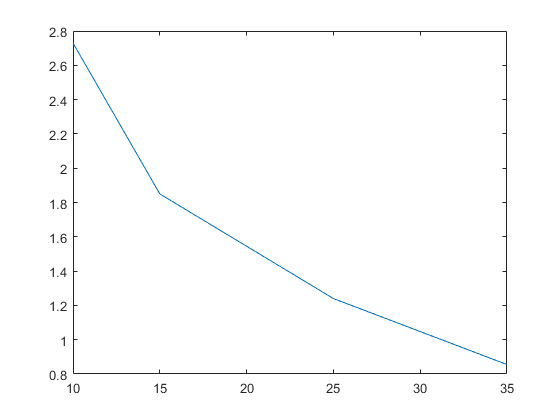

plot(angles, radius)

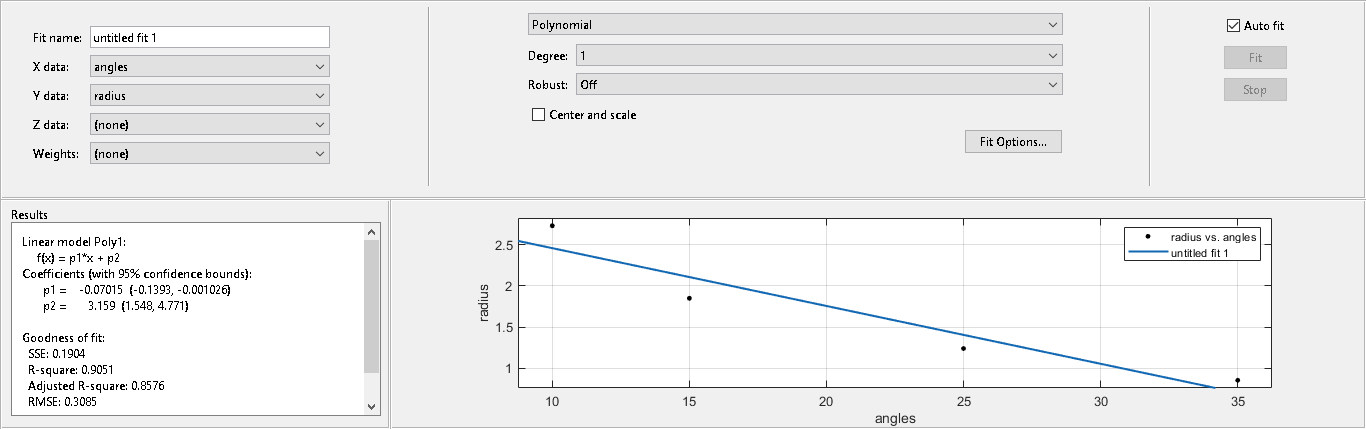

cftool(angles,radius)